algorithm in reverse procedure along Criss-Cross rule without any modify

If the arrangement is in the expression Ax=b, then the input is the coefficient matrix A_=[A|b]

% A_=[-1 0 -1
%     0 -1 -1
%     1 0 3
%     0 1 3
%     -1 1 -3]

tic
tim=10

tim = 10

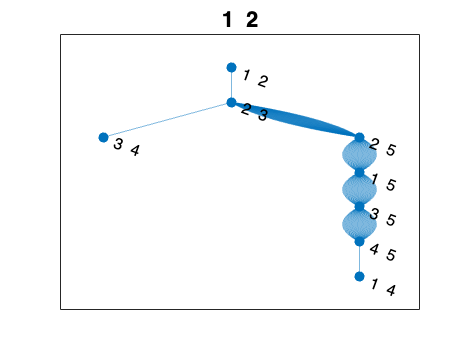

vertexes =      1     2
     2     3
     3     4
     4     5
     2     5
     1     5
     3     5
     4     5
     2     5
     1     5


[B,N,A]=dictionary_obj(A_);
vertexes=reverse(B,N,A,tim)

toc

Elapsed time is 10.257318 seconds.


This function aims to do recerse procedure along Criss-Cross rule from each optimal dictionary, and from each optimal dictionary give a subplot

function vertexes=reverse(B,N,A,tim)
optimal=findoptimal(B,N,A);
[op,~]=size(optimal);
vertexes=[];

for h=1:op
    B=optimal{h,1};
    N=optimal{h,2};
    A=optimal{h,3};
    N0=optimal{h,2};
    subplot(1,op,h)
    [reverseccrule,vertex]=reversecrisscross(B,N,A,tim);
    plot(reverseccrule,'Layout','layered')
    title(num2str(N0(2:end)))
    vertexes=[vertexes;vertex];
end
end

This function construct the initial dictionary from the given coefficient matrix of system, output the basis B, co-basis N, coefficient matrix of dictionary A

function [B,N,A]=dictionary_obj(A_)
A_=sym(A_);
[n,d]=size(A_);d=d-1;
A0=A_(:,1:end-1);b=A_(:,end);
A_N=[];N=[0];
[n,d]=size(A0);

for i=1:n
    if rank(A0(1:i,:))>rank(A0(1:i-1,:))
        A_N=[A_N;A0(i,:)];
        N=[N,i];
        if rank(A_N)==d
            break
        end 
    end
end

B=[setdiff(1:n,N(2:end)),n+1];

A=[[b(B(1:end-1)),zeros(n-d,d)]-A0(B(1:end-1),:)*inv(A_N)*[b(N(2:end)),-eye(d)];0,-ones(1,d)];
A=simplify(A);
for i=1:n-d
    if A(i,1)<0
        A(i,:)=-A(i,:);
    end
end
end

This function based on the given coefficient matrix of arrangement and obtained set of indexes N to comput all vertex after enumeration

function result=comput(result_dic,A_)
[ver,~]=size(result_dic);[~,n_]=size(A_);A_=[A_;-eye(n_)];A_=A_(1:end-1,:);
vertex=[];
for i=1:ver
    vert=inv(A_(result_dic(i,:),1:end-1))*A_(result_dic(i,:),end);
    vertex=[vertex;transpose(vert)];
end
result=sortrows(vertex);
end

This function based on the initial dictionary to generate all optimal dictionary using the Dual Bland's rule, record corresponding B,N,A

function optimal=findoptimal(B,N,A)
j=2;i=1;optimal={B,N,A};

B1=find(A(:,1)==0);
if length(B1)>1
subA=A(B1,:);subA(:,1)=[ones(length(B1)-1,1);0];
B1=B(B1); % subtract the sub dictionary out, and pivot parallel from the origion dictionary

while j<=length(N)+1
    if j<=length(N)
        reversedb=testdbreverse(B1,N,subA,i,j);
        if reversedb==1
            B2=B1(i);
            [B1,~,subA]=pivotrowcolumn(B1,N,subA,i,j);
            [B,N,A]=pivotrowcolumn(B,N,A,find(B==B2),j);
            optimal=[optimal;{B,N,A}];
            j=2;
            i=1;
        else
            i=i+1;
            if i==length(B1)
                i=1;j=j+1;
            end
        end
    else
        [i,j]=selectdb(subA);
        if (isempty(i)==0 && isempty(j)==0)
            Bi=B1(i);Nj=N(j);
            [B1,~,subA]=pivotrowcolumn(B1,N,subA,i,j);
            [B,N,A]=pivotrowcolumn(B,N,A,find(B==Bi),j);
            i=find(B1==Nj);j=find(N==Bi);
            i=i+1;
            if i==length(B1)
                i=1;j=j+1;
            end
        else
            break
        end
    end
end
end
end

This function based on input dictionary with set B,N,A do reverse along Criss-Cross rule, and output :

1, "vertex" each row is one set N passing lex-min test

2, "reverseccrule" represent a graph of spanning tree rooted at input N

function [reverseccrule,vertex]=reversecrisscross(B,N,A,tim)
vertex=[];

lexmin=lexicography(B,N,A);
if lexmin==1
    vertex=[vertex;N(2:end)];
end

s={};t={};
j=2;i=1;
while j<=length(N)+1
    if j<=length(N)
        reversecc=testccreverse(B,N,A,i,j);
        if reversecc==1
            s=[s,num2str(N(2:end))];
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            t=[t,num2str(N(2:end))];
            lexmin=lexicography(B,N,A);
            if lexmin==1
                vertex=[vertex;N(2:end)];
            end
            j=2;
            i=1;
        else
            i=i+1;
            if i==length(B)
                i=1;j=j+1;
            end
        end
    else
        [i,j]=selectcc(B,N,A);
        if (isempty(i)==0 && isempty(j)==0) && toc<=tim
            Bi=B(i);Nj=N(j);
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            i=find(B==Nj);j=find(N==Bi);
            i=i+1;
            if i==length(B)
                i=1;j=j+1;
            end
        else
            reverseccrule=graph(s,t);
            break
        end
    end
end
end

This function used to do pivot from input B,N,A and fixed pair B(i),N(j) as the i,j-th entry in A, output represent dictionary after update

function [B,N,A]=pivotrowcolumn(B,N,A,i,j)
C=sym(zeros(size(A)));
for l=1:length(B) %compute remainders in the pivot
    C(l,:)=A(l,:)-A(i,:)*A(l,j)/A(i,j);
end
C(i,:)=-A(i,:)/A(i,j); % compute the row in the pivot
C(:,j)=A(:,j)/A(i,j);C(i,j)=1/A(i,j); % compute the column the the fixed entry in pivot
N0=N;B0=B;
B(i)=N0(j);[B,I]=sort(B); % sort new B
N(j)=B0(i);[N,J]=sort(N); % sort new N
C=C(:,J);C=C(I,:);A=simplify(C); % permute the row and column of C in correspondence way
end

This function gives method to apply the Dual Bland's rule and give the position of this rule fixed as the i,j-th entery

function [i,j]=selectdb(A)
i=[];j=[];
i=find(A(1:end-1,1)<0);
if isempty(i)==0
    temp=find(A(i,2:end)>0)+1;
    radio=min(-A(end,temp)./A(i,temp));
    j=temp(min(find(-A(end,temp)./A(i,temp)==radio)));
end
end

This function gives method to test if i,j-th entery is a pair of valid Dual Bland's rule reverse, if yes, reversedb=1, otherwise =0

function reversedb=testdbreverse(B,N,A,i,j)
reversedb=0;
temp=find(A(i,2:end)>0)+1;
radio=min(-A(end,temp)./A(i,temp));
if ismember(j,temp(find(-A(end,temp)./A(i,temp)==radio)))==1
    B0=find(B<N(j));
    if all(A(i,1)*A(B0,j)<=A(B0,1)*A(i,j)) && A(i,1)>0
        N0=find(N<B(i));N0(1)=[];
        if all(A(end,intersect(N0,find(A(i,:)<0))))
            reversedb=1;
        end
    end
end
end

This function gives method to apply the Criss-Cross rule and give the position of this rule fixed as the i,j-th entery

function [i,j]=selectcc(B,N,A)
R=find(A(1:end-1,1)<0);S=find(A(end,2:end)>0)+1;
temp=min(union(B(R),N(S)));
if isempty(temp==1)
    i=[];j=[];
else
    if ismember(temp,N)==1
        j=find(N==temp);
        i=min(find(A(1:end-1,j)<0));
    else
        i=find(B==temp);j=min(find(A(i,2:end)>0)+1);
    end
end
end

This function gives method to test if i,j-th entery is a pair of valid Criss-Cross rule reverse, if yes, reversecc=1, otherwise =0

function reversecc=testccreverse(B,N,A,i,j)
reversecc=0;
if A(i,1)>0 && A(i,j)>0 && all(A(i,find(N(2:end)<B(i))+1)>=0)
    reversecc=1;
end

if A(end,j)<0 && A(i,j)<0 && all(A(find(B(1:end-1)<N(j)),j)<=0)
    reversecc=1;
end
end

This function gives method to test if the current dictionary pass the lex-min test, if yes, lexmin=1, otherwise =0


function lexmin=lexicography(B,N,A)
B0=B(find(A(1:end-1,1)==0));
lexmin=1;
if isempty(B0)==1
    lexmin=1;
else
    for i=length(B0):-1:1
        N0=find(N(2:end)<B0(i))+1;
        if isempty(N0)==0
            if any(A(find(B==B0(i)),N0)~=0)==1
                lexmin=0;
                break
            end
        else
            break
        end
    end
end

end